# Preprocesamiento de las imágenes 

close all; clc; clearvars;

Las imágenes están clasificadas en 2 grupos: 

- Sanos 

- Glaucoma 

Etiqueta de calidad con 5 categorías: 

- 0 - Imagen no revisada (se asume correcta, pero podría tener problemas de calidad) 

- 1 - Bajo contraste 

- 2 - Desenfoque 

- 3 - Ruido 

- 4 - Calidad correcta

## Caracteristicas calidad

- Extracción de caracteristicas

- Algoritmo de clasificación para las características extraídas

% T_metadata = readtable('metadata.csv');
% 
% T_revisada = T_metadata;
% T_revisada(T_revisada.quality == 0, :) = [];

### **Distribución categorias**

% %analisis exploratorio (EDA)
% num_bajocontraste = sum(T_revisada.quality == 1);
% num_desenfoque = sum(T_revisada.quality == 2);
% num_ruido = sum(T_revisada.quality == 3);
% num_calidadcorrecta = sum(T_revisada.quality == 4);
% 
% num_imagenes_revisadas = [num_bajocontraste, num_desenfoque, num_ruido, num_calidadcorrecta];
% bar(1:4, num_imagenes_revisadas);
% title('Cantidad de imágenes revisadas de cada categoría de calidad');
% xlabel('Categoría de calidad');
% ylabel('Número de imágenes');

### Extraer caracteristicas 

- **Entropia**: Las imágenes con bajo contraste tienden a tener una entropía baja, ya que tienen menos variación en los niveles de intensidad de píxeles.

- **Minima y maxima intensidad**

- **Rango dinamico: **Diferencia entre el valor máximo y mínimo de los píxeles en una imagen. 

- **Desviación estandar y varianza de la intensidad:** Indica la variabilidad de los niveles de gris en una imagen

- **Nitidiez del borde: **La nitidez de borde mide la cantidad de cambios en la intensidad de los píxeles en una imagen, lo que puede indicar la presencia de bordes nítidos y detalles finos.

- **MSE (Error cuadrático medio) y PSNR (Relación señal-ruido pico): **Evalua la calidad de la imagen en comparación con una imagen de referencia.

- **Score de BRISQUE:** Es un algoritmo de evaluación de calidad de imágenes sin referencia que se basa en características estadísticas de la imagen. Proporciona un puntaje que puede indicar la calidad de la imagen.

% [n, m] = size(T_revisada);
% 
% entropia = zeros(n,1);
% min_intensidad= zeros(n, 1);
% max_intensidad= zeros(n, 1);
% rango_dinamico= zeros(n, 1);
% std_intensidad= zeros(n, 1);
% var_intensidad= zeros(n, 1);
% nitidez_borde = zeros(n, 1);
% score = zeros(n, 1);
% mse = zeros(n, 1);
% magnitud_transformada_promedio = zeros(n, 1);
% snr = zerons(n,1);
% filtro_laplace=[1, 1, 1; 1, -8, 1; 1, 1, 1];
% 
% for i = 1:n
%     I = imread(T_revisada.image{i});
%     entropia(i) = entropy(I);
% 
%     I = double(rgb2gray(I)); % damos por hecho que la imagen es de color (igual hacer un for para diferenciar)
% 
%     min_intensidad(i)=min(I(:));
%     max_intensidad(i)=max(I(:));
%     rango_dinamico(i)=max(I(:))-min(I(:));
%     std_intensidad(i) = std2(I(:)); % desviación estandar
%     var_intensidad(i) =var(I(:)); % varianza
% 
%     I2=imfilter(I, filtro_laplace);
%     nitidez_borde(i) = sum(abs(I2(:)));
% 
%     I_filtrada=medfilt2(I);
%     mse(i)=immse(I_filtrada, I); %Cuanto menor sea el valor del MSE, menor será la diferencia entre las dos imágenes, lo que indica una mejor calidad de la imagen.
%     snr(i)=psnr(I_filtrada, I); 
%     score(i) = brisque(I);
% 
%     transformada = fft2(I);
%     magnitud_transformada = abs(transformada);
%     magnitud_transformada_promedio(i) = mean(magnitud_transformada(:));
% end
% 
% T_caracteristicas = table(T_revisada.quality, entropia, min_intensidad, max_intensidad, rango_dinamico, std_intensidad, var_intensidad, nitidez_borde, mse, snr, score, magnitud_transformada_promedio, 'VariableNames', {'quality', 'entropia', 'min_intensidad', 'max_intensidad', 'rango_dinamico', 'std_intensidad', 'var_intensidad', 'nitidez_borde', 'mse', 'snr', 'score', 'magnitud_transformada_promedio'});
% T_caracteristicas.imagen = T_revisada.image;

### Save table 

% writetable(T_caracteristicas, 'CaracteristicasCalidadREVISADAS_TODAS.csv');

## Desarrollo modelo

### 1. Load data

T = readtable("CaracteristicasCalidadREVISADAS_TODAS2.csv");

#### Correlation

T.min_intensidad=[];

variables = 1×34 cell array
    {'entropia'}    {'entropiaR'}    {'entropiaG'}    {'entropiaB'}    {'rango_dinamico'}    {'rango_dinamicoR'}    {'rango_dinamicoG'}    {'rango_dinamicoB'}    {'std_intensidad'}    {'var_intensidad'}    {'var_intensidadR'}    {'var_intensidadG'}    {'var_intensidadB'}    {'CDR'}    {'DDLS'}    {'dist1'}    {'dist2'}    {'dist3'}    {'dist4'}    {'radioC'}    {'radioD'}    {'centro1'}    {'centro2'}    {'NRR_area_ratio'}    {'media'}    {'media_r'}    {'media_g'}    {'media_b'}    {'nitidez_borde'}    {'nitidez_bordeR'}    {'nitidez_bordeG'}    {'nitidez_bordeB'}    {'imagen'}    {'glaucoma'}


T.max_intensidad=[];

Error using  {} 
Unable to concatenate
the table variables
'entropia' and
'imagen', because their
types are double and
cell.

T.magnitud_transformada_promedio=[];
% T.mse=[];
% T.snr=[];
T.nitidez_borde=[];
% T.var_intensidad=[];
T.std_intensidad=[];
T.score=[];

variables=T.Properties.VariableNames
X = T{:, 1:end-1};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure;
imagesc(R); clim([-1 1]);
xticks(1:30);
xticklabels(variables(:));
yticks(1:30);
yticklabels(variables(:));
colormap(jet); colorbar;

figure;
imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:30);
xticklabels(variables(:));
yticks(1:30);
yticklabels(variables(:));

#### Preprocessing

T.imagen=[];

% caracteristicas para el modelo: entropia, rango_dinamico, std_intensidad, snr

[n, ~]=size(T);

T.quality = cellstr(num2str(T.quality)); %convertir quality en variable categorica
for i = 1:n
    if T.quality{i} == '1'
        T.quality{i} = 'Bajo Contraste';
    elseif T.quality{i} == '2'
        T.quality{i} = 'Desenfoque';
    elseif T.quality{i} == '3'
        T.quality{i} = 'Ruido';
    elseif T.quality{i} == '4'
        T.quality{i} = 'Calidad Correcta';
    end
end

### 2. Data split

rng(4); 
p = 0.2;
cv_out = cvpartition(T.quality, 'HoldOut', p, 'Stratify', true); 
% 20% -> pruebas
% 80% -> entrenar el modelo. 
% 'Stratify', true asegura que la distribución de clases se mantenga tanto en los conjuntos de entrenamiento como en los de prueba

T_train = T(cv_out.training, :); 
T_test  = T(cv_out.test, :);

k = 10; % técnica de validación cruzada de 10 pliegues
cv_in = cvpartition(T_train.quality, 'KFold', k, 'Stratify', true);

### **3. Model training**

results = table;

#### **K-nearest neighbors (KNN)**

mdl_knn = fitcknn(T_train, 'quality', 'NumNeighbors', 3, 'CVPartition', cv_in); % number of neighbors: 3
mdl_loss = kfoldLoss(mdl_knn); % mean error value

Y_pred = kfoldPredict(mdl_knn);

accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);
results = [results; table("knn", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### **Classification Trees**

mdl_tree = fitctree(T_train, 'quality', 'CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_tree);

Y_pred = kfoldPredict(mdl_tree);

accuracy = sum(strcmp(T_train.quality, Y_pred)) / height(T_train);
results = [results; table("tree", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### Naive Bayes

mdl_NB = fitcnb(T_train, 'quality','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_NB);

Y_pred = kfoldPredict(mdl_NB);

accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);
results = [results; table("naive_bayes", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### Discriminant Analysis

- **LDA**: asume que las matrices de covarianza de cada clase son iguales.

mdl_lda = fitcdiscr(T_train, 'quality','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_lda);
Y_pred = kfoldPredict(mdl_lda);
accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);

results = [results; table("LDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

- **QDA:** asume que las matrices de covarianza de cada clase son diferentes.

mdl_qda = fitcdiscr(T_train, 'quality','DiscrimType','quadratic','CVPartition',cv_in);
mdl_loss = kfoldLoss(mdl_qda);

Y_pred = kfoldPredict(mdl_qda);

accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);
results = [results; table("QDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### **Support Vector Machines (SVM)**

mdl_svm = fitcecoc(T_train, 'quality','CVPartition',cv_in);
mdl_loss = kfoldLoss(mdl_svm);

Y_pred = kfoldPredict(mdl_svm);

loss_final2 = 0.0161


accuracy = sum(strcmp(Y_pred, T_train.quality)) / height(T_train);
results = [results; table("SVM", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

### 4. Model comparison

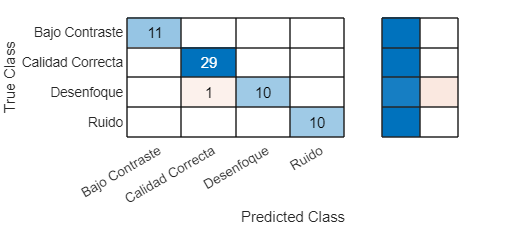

results
[~, best_model] = max(results.accuracy);

results(best_model, :) %balance accuracy

### 5. Final model testing

#### **Support Vector Machines (SVM)**

mdl_final_SVM = fitcecoc(T_train, 'quality');
Y_pred2 = predict(mdl_final_SVM, T_test);

loss_final2 = loss(mdl_final_SVM, T_test)
accuracy_final2 = sum(strcmp(Y_pred2, T_test.quality)) / height(T_test.quality);

Y_test  = T.quality(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized')

mdl_final_TODO_SVM = fitcecoc(T, 'quality');

## Caracteristicas de imagenes no revisadas

% no_revisadas = T_metadata.image(T_metadata.quality == 0);

### Extraer caracteristicas 

% [n, m] = size(no_revisadas);
% 
% entropia2 = zeros(n,1);
% min_intensidad2= zeros(n, 1);
% max_intensidad2= zeros(n, 1);
% rango_dinamico2= zeros(n, 1);
% std_intensidad2= zeros(n, 1);
% var_intensidad2= zeros(n, 1);
% nitidez_borde2 = zeros(n, 1);
% score2 = zeros(n, 1);
% mse2 = zeros(n, 1);
% magnitud_transformada_promedio2 = zeros(n, 1);
% snr2 = zeros(n,1);
% 
% filtro_laplace=[1, 1, 1; 1, -8, 1; 1, 1, 1];
% 
% for i = 1:n
%     I = imread(no_revisadas{i});
%     entropia2(i) = entropy(I);
% 
%     I = double(rgb2gray(I)); % damos por hecho que la imagen es de color (igual hacer un for para diferenciar)
% 
%     min_intensidad2(i)=min(I(:));
%     max_intensidad2(i)=max(I(:));
%     rango_dinamico2(i)=max(I(:))-min(I(:));
%     std_intensidad2(i) = std2(I(:)); % desviación estandar
%     var_intensidad2(i) =var(I(:)); % varianza
% 
%     I2=imfilter(I, filtro_laplace);
%     nitidez_borde2(i) = sum(abs(I2(:)));
% 
%     I_filtrada=medfilt2(I);
%     mse2(i)=immse(I_filtrada, I);
%     snr2(i)=psnr(I_filtrada, I);
% 
%     score2(i) = brisque(I);
% 
%     transformada = fft2(I);
%     magnitud_transformada = abs(transformada);
%     magnitud_transformada_promedio2(i) = mean(magnitud_transformada(:));
% end
% 
% T_caracteristicas_norevisadas = table(entropia2, min_intensidad2, max_intensidad2, rango_dinamico2, std_intensidad2, var_intensidad2, nitidez_borde2, mse2, snr2, score2, magnitud_transformada_promedio2, 'VariableNames', {'entropia', 'min_intensidad', 'max_intensidad', 'rango_dinamico', 'std_intensidad', 'var_intensidad', 'nitidez_borde', 'mse', 'snr', 'score', 'magnitud_transformada_promedio'});
% variables=T_caracteristicas.Properties.VariableNames;
% % 
% % T_caracteristicas_norevisadas.imagen = no_revisadas.image;

### Save table 

% writetable(T_caracteristicas_norevisadas, 'CaracteristicasCalidadNOREVISADAS_TODAS.csv');

## Predicción

T_metadata = readtable('metadata.csv');
no_revisadas = T_metadata.image(T_metadata.quality == 0);
T_caracteristicas_norevisadas = readtable("CaracteristicasCalidadNOREVISADAS_TODAS2.csv");

#### **Support Vector Machines (SVM)**

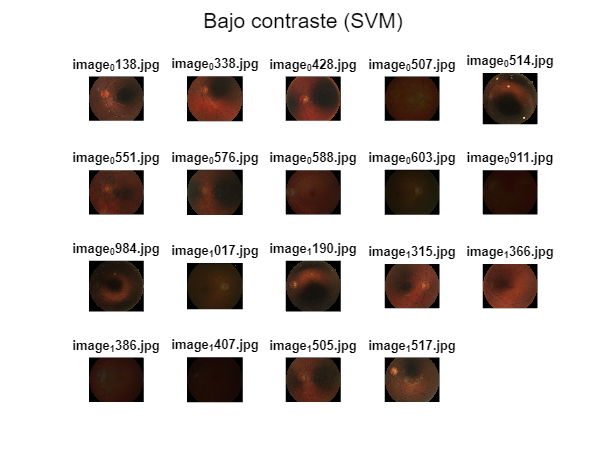

prediccion4 = predict(mdl_final_TODO_SVM, T_caracteristicas_norevisadas);
T_calidad4 = table(no_revisadas, prediccion4, 'VariableNames', {'Imagen', 'Calidad'});
Bajo_contraste_SVM = T_calidad4.Imagen(strcmp(T_calidad4.Calidad, 'Bajo Contraste'));
Calidad_correcta_SVM = T_calidad4.Imagen(strcmp(T_calidad4.Calidad, 'Calidad Correcta'));
Ruido_SVM = T_calidad4.Imagen(strcmp(T_calidad4.Calidad, 'Ruido'));
Desenfoque_SVM = T_calidad4.Imagen(strcmp(T_calidad4.Calidad, 'Desenfoque'));

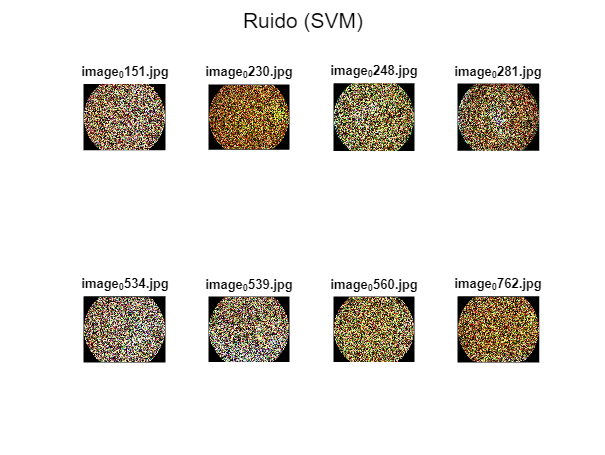

figure; sgtitle('Bajo contraste (SVM)')
for i=1:19
   subplot(4,5,i); imshow(Bajo_contraste_SVM{i}); title(Bajo_contraste_SVM{i})
end

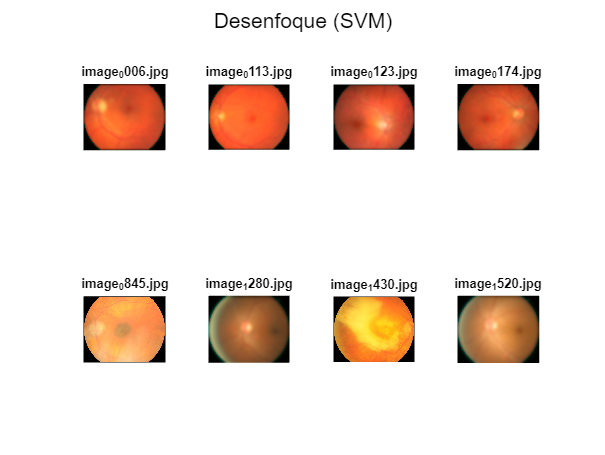


figure; sgtitle('Ruido (SVM)')
for i=1:8
   subplot(2,4,i); imshow(Ruido_SVM{i});title(Ruido_SVM{i})
end


figure; sgtitle('Desenfoque (SVM)')
for i=1:8
   subplot(2,4,i); imshow(Desenfoque_SVM{i}); title(Desenfoque_SVM{i})
end

%poner los resultados, mirar las distintos porcentajes que te da de cada
%medida (igual se puede poner mas estricto)
% creo q hay alguna de desenfoque esta mal


% luego podemos clasificar mas 

carpeta_calidad_correcta = 'imagenes_calidad_correcta_SVM';
mkdir(carpeta_calidad_correcta);

% Iterar sobre las imágenes y guardarlas en la carpeta
for i = 1:numel(Calidad_correcta_SVM)
    % Obtener el nombre de la imagen
    nombre_imagen = Calidad_correcta_SVM{i};
    
    % Leer la imagen desde su ubicación original (o donde sea que estén almacenadas)
    imagen = imread(nombre_imagen);
    
    % Guardar la imagen en la carpeta
    [~, nombre_sin_extension, extension] = fileparts(nombre_imagen);
    nombre_imagen_guardada = fullfile(carpeta_calidad_correcta, [nombre_sin_extension, extension]);
    imwrite(imagen, nombre_imagen_guardada);
end

## Imagenes calidad correcta

T_metadata = readtable('metadata.csv');
I_calidadcorrecta = [T_metadata.image(T_metadata.quality == 4, :); Calidad_correcta_SVM];

T_calidadcorrecta = T_metadata(ismember(T_metadata.image, I_calidadcorrecta), :);

writetable(T_calidadcorrecta, 'metadataCALIDADCORRECTA.csv');